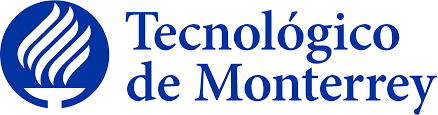

### Fundamentación de robótica (TE3001B)

## Examen Final 6 (Torque y fuerzas) Parte 1

### Pamela Hernández Montero A0173636

**Objetivo**

Obtener el modelo del torque de cada articulación, la matriz de inercia, el modelo de las fuerzas centripetas y de Coriolis y el modelo del par gravitacional para un robot de 1GDL.

**Introducción:**

La cinemática de un robot se refiere a la descripción geométrica del movimiento y no en las causas físicas que lo generan; permite determinar la posición y orientación del extremo del robot en función de las posiciones de sus articulaciones.

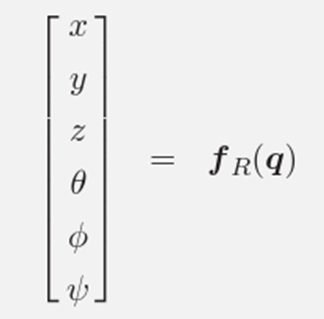

Por otro lado la cinemática diferencial relaciona las velocidades de las articulaciones y las velocidades resultantes del extremo del robot. La cinemática diferencial directa es la derivada con respecto al tiempo de la cinemática directa.

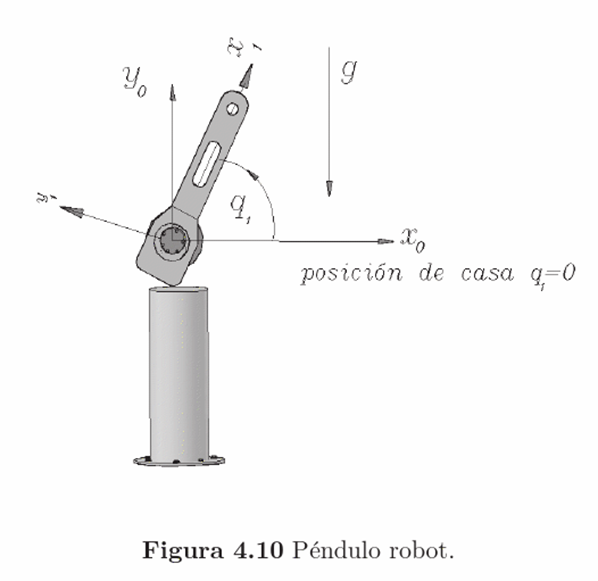

%Limpieza de pantalla
clear all
close all
clc

Se definen variables simbólicas para representar el ángulo de la articulación, su velocidad y aceleración, así como parámetros físicos como la masa, los momentos de inercia y la geometría del eslabón. Se configura el robot como una junta rotacional y se calcula el número de grados de libertad del sistema. 

%Declaración de variables simbólicas
syms th1(t) t  %Angulo de la articulación
syms th1p(t)   %Velocidad de la articulación
syms th1pp(t)  %Aceleración de la articulación
syms m1  Ixx1 Iyy1 Izz1   %Masa y matrices de Inercia
syms l1 lc1   %l=longitud del eslabon y lc=distancia al centro de masa del eslabón
syms pi g a cero

%Creamos el vector de coordenadas articulares
Q= [th1];
%Creamos el vector de velocidades articulares(1GDL)
Qp= [th1p];
%Creamos el vector de aceleraciones articulares(1GDL)
Qpp= [th1pp]; %se utiliza este formato para simplificar la impresion de resultados

%Configuración del robot, 0 para junta rotacional, 1 para junta prismática
RP=[0];

%Número de grado de libertad del robot
GDL= size(RP,2);
GDL_str= num2str(GDL);

Se describe la construcción de la matriz homogénea.

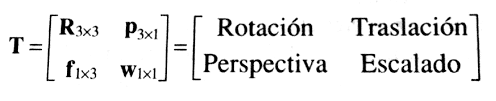

%Articulación 1 
%Posición de la articulación 1 respecto a 0
P(:,:,1)= [l1*cos(th1); l1*sin(th1);0];
%Matriz de rotación de la junta 1 respecto a 0.... 
R(:,:,1)= [cos(th1) -sin(th1)  0;
           sin(th1)  cos(th1)  0;
           0         0         1];
%Creamos un vector de ceros perteneciente a la perspectiva
Vector_Zeros= zeros(1, 3);

Se establece las bases para representar la transformación y características espaciales del robot.

%Inicializamos las matrices de transformación Homogénea locales
A(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las matrices de transformación Homogénea globales
T(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las posiciones vistas desde el marco de referencia inercial
PO(:,:,GDL)= P(:,:,GDL); 
%Inicializamos las matrices de rotación vistas desde el marco de referencia inercial
RO(:,:,GDL)= R(:,:,GDL); 

Calcular las matrices de transformación tanto locales como globales para cada articulación.

for i = 1:GDL
   i_str= num2str(i);
   disp(strcat('Matriz de Transformación local A', i_str));
   A(:,:,i)=simplify([R(:,:,i) P(:,:,i); Vector_Zeros 1]);
   pretty (A(:,:,i));
   %Globales
    try
       T(:,:,i)= T(:,:,i-1)*A(:,:,i);
    catch
       T(:,:,i)= A(:,:,i);
    end
    disp(strcat('Matriz de Transformación global T', i_str));
    T(:,:,i)= simplify(T(:,:,i));
    pretty(T(:,:,i))
    RO(:,:,i)= T(1:3,1:3,i);
    PO(:,:,i)= T(1:3,4,i);
end

Matriz de Transformación local A1


/ cos(th1(t)), -sin(th1(t)), 0, l1 cos(th1(t)) \
|                                              |
| sin(th1(t)),  cos(th1(t)), 0, l1 sin(th1(t)) |
|                                              |
|      0,            0,      1,        0       |
|                                              |
\      0,            0,      0,        1       /



Matriz de Transformación global T1


/ cos(th1(t)), -sin(th1(t)), 0, l1 cos(th1(t)) \
|                                              |
| sin(th1(t)),  cos(th1(t)), 0, l1 sin(th1(t)) |
|                                              |
|      0,            0,      1,        0       |
|                                              |
\      0,            0,      0,        1       /



El Jacobiano es una matriz que relaciona las velocidades de las articulaciones del robot con las velocidades del extremo del robot en el espacio de trabajo. Se ocupa para analizar la cinemática del robot y entender cómo los cambios en las velocidades de las articulaciones afectan el movimiento del extremo del robot.

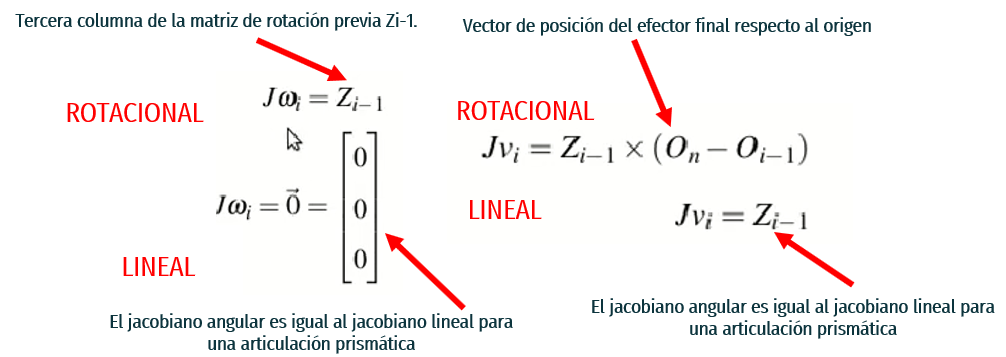

%Calculamos el jacobiano lineal de forma analítica
Jv_a(:,GDL)=PO(:,:,GDL);
Jw_a(:,GDL)=PO(:,:,GDL);

for k= 1:GDL
    if RP(k)==0 
       %Para las juntas de revolución
        try
            Jv_a(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL)-PO(:,:,k-1));
            Jw_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)= cross([0,0,1], PO(:,:,GDL));
            Jw_a(:,k)=[0,0,1];
         end
     else
        %Para las juntas prismáticas
        try
            Jv_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)=[0,0,1];
        end
            Jw_a(:,k)=[0,0,0];
     end
end 
%Obtenemos SubMatrices de Jacobianos
Jv_a = simplify(Jv_a);
Jw_a = simplify(Jw_a);
disp("Jacobiano lineal obtenido de forma analítica"); pretty(Jv_a);

Jacobiano lineal obtenido de forma analítica
/ -l1 sin(th1(t)) \
|                 |
|  l1 cos(th1(t)) |
|                 |
\        0        /



disp('Jacobiano ángular obtenido de forma analítica');pretty (Jw_a);

Jacobiano ángular obtenido de forma analítica
/ 0 \
|   |
| 0 |
|   |
\ 1 /



%Matriz de Jacobiano Completa
Jac= [Jv_a;
      Jw_a];
Jacobiano= simplify(Jac);
disp('Matriz de Jacobiano');pretty(Jacobiano);

Matriz de Jacobiano
/ -l1 sin(th1(t)) \
|                 |
|  l1 cos(th1(t)) |
|                 |
|        0        |
|                 |
|        0        |
|                 |
|        0        |
|                 |
\        1        /



Con el Jacobiano obtenemos vectores de velocidades lineales y angulares que describen cómo cambian las posiciones y orientaciones del extremo del robot en respuesta a las velocidades de las articulaciones. 

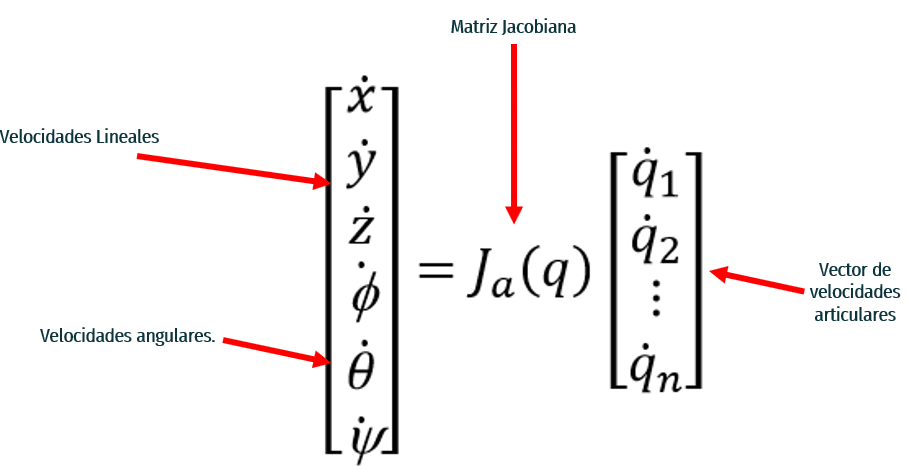

%Obtenemos vectores de Velocidades Lineales y Angulares
V =  simplify(Jv_a*Qp');
disp("Velocidad lineal obtenida mediante el Jacobiano lineal"); pretty(V);

Velocidad lineal obtenida mediante el Jacobiano lineal
/     _______             \
| -l1 th1p(t) sin(th1(t)) |
|                         |
|     _______             |
|  l1 th1p(t) cos(th1(t)) |
|                         |
\            0            /



W = simplify(Jw_a*Qp');
disp("Velocidad angular mediante el Jacobiano angular"); pretty(W);

Velocidad angular mediante el Jacobiano angular
/    0    \
|         |
|    0    |
|         |
| _______ |
\ th1p(t) /



A continuación se calcula la energía cinética de un eslabón del robot y obtiene los vectores de velocidades lineales y angulares asociados. Primero, se define la posición del **centro de masa** del eslabón respecto al origen y se crean **matrices de inercia** para el eslabón utilizando sus momentos principales. Luego, se extraen las **velocidades lineales y angulares **del robot en cada eje del espacio. Posteriormente, se calculan las velocidades para cada eslabón del robot utilizando el Jacobiano lineal y angular obtenido de forma analítica previamente. Esto se logra calculando las derivadas de las posiciones del extremo del robot respecto a las velocidades de las articulaciones. Finalmente, se obtienen los vectores de velocidades lineales y angulares asociados al eslabón del robot,

%Energía Cinética

%Distancia del origen del eslabón a su centro de masa
%Vectores de posición respecto al centro de masa
%La función subs sustituye l1 por lc1 en la expresión P(:,:,1)/2
P01=subs(P(:,:,1)/2, l1, lc1);

%Creamos matrices de inercia para cada eslabón
%Momentos principales
I1=[Ixx1 0 0; 
    0 Iyy1 0; 
    0 0 Izz1];

%Extraemos las velocidades lineales en cada eje
V=V(t);
Vx= V(1,1);
Vy= V(2,1);
Vz= V(3,1);

%Extraemos la velocidad angular en cada ángulo de Euler
W=W(t);
W_pitch= W(1,1);
W_roll= W(2,1);
W_yaw= W(3,1);

%Calculamos las velocidades para cada eslabón 
%Ya lo calculamos previamente al multiplicar la matriz jacobiana por Qp
%Calculamos la energía cinética para cada uno de los eslabones

%Calculamos el jacobiano lineal y angular de forma analítica
Jv_a1(:,GDL)=PO(:,:,GDL);
Jw_a1(:,GDL)=PO(:,:,GDL);

for k= 1:GDL
    if RP(k)==0 
       %Para las juntas de revolución
        try
            Jv_a1(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL)-PO(:,:,k-1));
            Jw_a1(:,k)= RO(:,3,k-1);
        catch
            Jv_a1(:,k)= cross([0,0,1], PO(:,:,GDL));%Matriz de rotación de 0 con respecto a 0 es la Matriz Identidad, la posición previa tambien será 0
            Jw_a1(:,k)=[0,0,1];%Si no hay matriz de rotación previa se obtiene la Matriz identidad
         end
     else
        %Para las juntas prismáticas
        try
            Jv_a1(:,k)= RO(:,3,k-1);
        catch
            Jv_a1(:,k)=[0,0,1];
        end
            Jw_a1(:,k)=[0,0,0];
     end
 end    

%Obtenemos SubMatrices de Jacobianos
Jv_a1= simplify (Jv_a1);
Jw_a1= simplify (Jw_a1);

%Matriz de Jacobiano Completa
Jac1= [Jv_a1;
      Jw_a1];
Jacobiano1= simplify(Jac1);

%Obtenemos vectores de Velocidades Lineales y Angulares
Qp=Qp(t);
V1=simplify (Jv_a1*Qp(1));
W1=simplify (Jw_a1*Qp(1));

Energia cinetica = Energia cinetica traslacional + Energia cinetica rotacional

La energía cinética describe la capacidad de un objeto en movimiento para realizar trabajo y causar cambios en su entorno durante una interacción.

%Calculamos la energía cinética para cada uno del eslabon
V1_Total= V1+cross(W1,P01);
K1= (1/2*m1*(V1_Total))'*((V1_Total)) + (1/2*W1)'*(I1*W1);
disp('Energía Cinética en el Eslabón 1');pretty (K1)

Energía Cinética en el Eslabón 1
                                                        /                 _______    ___ \                                                           /                 _______    ___ \
__ / lc1 cos(th1(t)) th1p(t)                          \ | _______    __   th1p(t) #2 lc1 |   __ /                          lc1 sin(th1(t)) th1p(t) \ | _______    __   th1p(t) #1 lc1 |
m1 | ----------------------- + l1 cos(th1(t)) th1p(t) | | th1p(t) #2 l1 + -------------- |   m1 | l1 sin(th1(t)) th1p(t) + ----------------------- | | th1p(t) #1 l1 + -------------- |        _______
   \            2                                     / \                        2       /      \                                     2            / \                        2       /   Izz1 th1p(t) th1p(t)
------------------------------------------------------------------------------------------ + ------------------------------------------------------------------------------------------ + -------

K1= simplify (K1);
K_Total= simplify (K1);pretty (K_Total)

              2            2     ______           __          2             2
Izz1 |th1p(t)|    |th1p(t)|  cos(th1(t) - th1(t)) m1 (l1 |lc1|  + 2 lc1 |l1| ) (2 l1 + lc1)
--------------- + -------------------------------------------------------------------------
       2                                           8 l1 lc1



Energia potencial gravitatoria

Se define como la energía que un objeto posee debido a su altura en relación con una referencia definida en el campo gravitatorio. 

%Obtenemos las alturas respecto a la gravedad
h1= P01(2); %Tomo la altura paralela al eje y
U1=m1*g*h1;

%Calculamos la energía potencial total
U_Total= U1 

$$U\_Total = \frac{g\,{\mathrm{lc}}_{1}\,m_{1}\,\sin\left({\mathrm{th}}_{1}\left(t\right)\right)}{2}$$

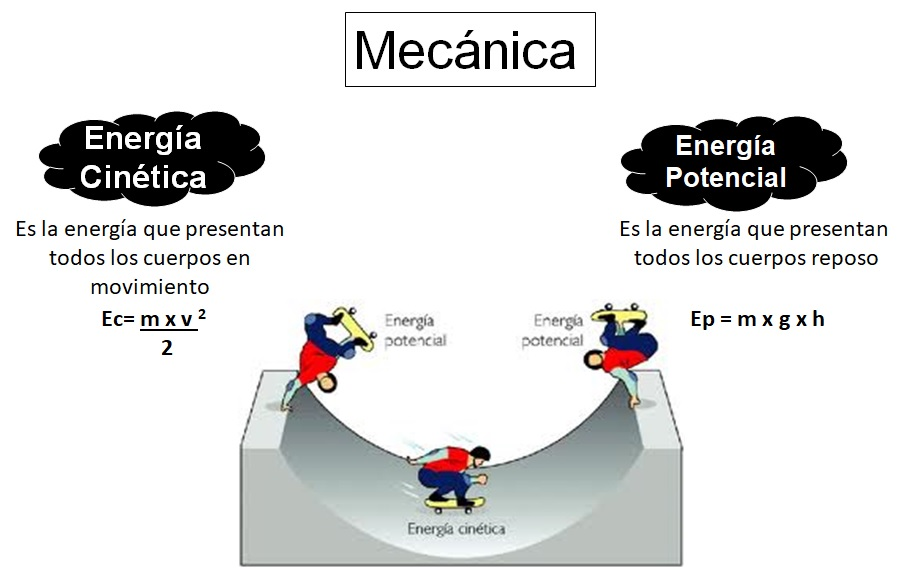

Estas energias son fundamentales para diseñar robots seguros, eficientes y capaces de realizar tareas de manera autónoma y precisa. La **energía cinética **permite evaluar la **velocidad** y el** movimiento** del robot, lo que es crucial para prevenir colisiones y garantizar un movimiento suave y controlado. Por otro lado, la **energía potencial** proporciona información sobre la **estabilidad** y el** equilibrio **del robot, lo que es esencial para evitar caídas y asegurar una operación segura en diversas condiciones. 

El uso del Lagrangiano ofrece una manera elegante y eficiente de describir su dinámica y comportamiento. En mecánica clásica, el Lagrangiano, denotado típicamente como *L*, es una función que depende de las coordenadas generalizadas del sistema, así como de sus velocidades y posiblemente del tiempo. Matemáticamente, se define como la diferencia entre la energía cinética *T* y la energía potencial *V* del sistema:

*L*=*T*−*V*

Lagrangiano= simplify (K_Total-U_Total); pretty (Lagrangiano)

              2                                   2     ______           __          2             2
Izz1 |th1p(t)|    g lc1 m1 sin(th1(t))   |th1p(t)|  cos(th1(t) - th1(t)) m1 (l1 |lc1|  + 2 lc1 |l1| ) (2 l1 + lc1)
--------------- - -------------------- + -------------------------------------------------------------------------
       2                    2                                             8 l1 lc1



%Modelo de Energía
 H= simplify (K_Total+U_Total);pretty (H)

              2                                   2     ______           __          2             2
Izz1 |th1p(t)|    g lc1 m1 sin(th1(t))   |th1p(t)|  cos(th1(t) - th1(t)) m1 (l1 |lc1|  + 2 lc1 |l1| ) (2 l1 + lc1)
--------------- + -------------------- + -------------------------------------------------------------------------
       2                    2                                             8 l1 lc1



%Lagrangiano derivado con respecto a la primera coordenada generalizada de
%velocidad

%Definimos un vector columna de derivadas con respecto al tiempo
%En este vector agrego las velocidades y aceleraciones
%Derivadas respecto al tiempo
Qd=[th1p(t); th1pp(t)];

%Obtenemos las derivadas de la velocidad en la primera coordenada
%generalizada
dQ1=[diff(diff(Lagrangiano,th1p), th1),... %Derivamos con respecto a la primera velocidad generalizada th1p para las 3 posiciones articulaciones
 diff(diff(Lagrangiano,th1p), th1p)];%Derivamos con respecto a la primera velocidad generalizada th1p para las 3 velocidades articulaciones

%Definimos el torque 1
t1= dQ1*Qd- diff(Lagrangiano, th1);

%Generación del Modelo Dinámico en forma matricial

%Matriz de Inercia
%Extraemos coeficientes de aceleraciones derivamos torque uno con respecto a la aceleracion
M=[diff(t1, th1pp)];
rank (M);

M=M(t);
disp('Matriz de inercia ='); pretty(M)

Matriz de inercia =
                                                                      __                                __                          __
Izz1 |th1p(t)|        Izz1 #2        Izz1 |th1p(t)| #2   |th1p(t)| #3 m1 #1 (2 l1 + lc1)   |th1p(t)| #3 m1 #1 #2 (2 l1 + lc1)    #3 m1 #1 #2 (2 l1 + lc1)
-------------- + ----------------- - ----------------- + ------------------------------- - ---------------------------------- + -------------------------
   sqrt(#4)        _______                    3/2               4 l1 lc1 sqrt(#4)                                3/2                      _______
                 4 th1p(t) th1p(t)        4 #4                                                       16 l1 lc1 #4               16 l1 lc1 th1p(t) th1p(t)

where

                 2             2
   #1 == l1 |lc1|  + 2 lc1 |l1|

          _______           2
   #2 == (th1p(t) + th1p(t))

             ______
   #3 == cos(th1(t) - th1(t))

         _______
   #4 == th1p(t) th1p(t)




%Fuerzas Centrípetas y de Coriolis

%Definimos Mp
Mp=[diff(M,th1p)]*Qp;%Se deriva parcialmente en el tiempo respecto a todas las variables 

%Definimos la energía cinética en su forma matricial
k=1/2*transpose(Qp)*M*Qp;

%Definimos dk
dk=[diff(k, th1)];

%Fuerzas centrípetas y de Coriolis
C= Mp*Qp-dk;
disp('Fuerzas centrípetas y de Coriolis =');pretty(C)

Fuerzas centrípetas y de Coriolis =
           /                                                                         2                 2               3                        3                                    __      3                      __                         __                                   __                                   __                                                                             __      3              \
         2 | Izz1 |th1p(t)| #1        Izz1 #7        Izz1 |th1p(t)| #7        Izz1 #7           Izz1 #7         Izz1 #7      3 Izz1 |th1p(t)| #7         Izz1 #1        |th1p(t)| #6 m1 #5 #7  (2 l1 + lc1) 3    #6 m1 #5 #1 (2 l1 + lc1)   #6 m1 #5 #7 (2 l1 + lc1)   |th1p(t)| #6 m1 #5 #1 (2 l1 + lc1)   |th1p(t)| #6 m1 #5 #7 (2 l1 + lc1)               #4                        #4            #6 m1 #5 #7  (2 l1 + lc1) |
- th1p(t)  | ----------------- - ----------------- + ----------------- + ------------------ + ------------ + ------------- - -----

%Par Gravitacional se sustituyen las velocidades y aceleraciones por 0
r=cero;
a1=subs(t1, th1p, r);

%Torque gravitacional en el motor 1
G1=a1;

% Vector de par gravitacional
G=[G1];
disp('Modelo de par gravitacional =');pretty(G)

Modelo de par gravitacional =
         /                                                            __                             __                         __                    \
         |   Izz1 |cero|     Izz1 |cero| #3     Izz1 #3     #2 |cero| m1 #1 (2 l1 + lc1)   #2 |cero| m1 #1 #3 (2 l1 + lc1)   #2 m1 #1 #3 (2 l1 + lc1) |   g lc1 m1 cos(th1(t))
th1pp(t) | --------------- - -------------- + ----------- + ---------------------------- - ------------------------------- + ------------------------ | + --------------------
         |           ____         4 #4               ____                        ____                16 l1 lc1 #4                              ____   |             2
         \ sqrt(cero cero)                    4 cero cero     4 l1 lc1 sqrt(cero cero)                                          16 cero l1 lc1 cero   /

where

                 2             2
   #1 == l1 |lc1|  + 2 lc1 |l1|

             ______
   #2 == cos(th1(t) - th1(t))

                 ____ 2
 